clc
clear

% Preparation
n=4;                                          % The order of the polynominal
func=@(x)x.^2.*log(2+x);
syms y;
Tn=[1,y,cos(2.*acos(y)),cos(3.*acos(y)),cos(4.*acos(y))];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Best square approximation
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Get the coefficient
a_sqr=sqr_approx(n,func);   

gmres converged at iteration 5 to a solution with relative residual 0.



% Get approximated function
func_sqr=@(x)0;                                                                     
for i=1:n+1
    func_sqr=@(x)func_sqr(x)+a_sqr(i).*x.^(i-1);
end

% Start approximating
x_input=-1:0.01:1;
y_real=func(x_input);
y_sqr=func_sqr(x_input);

% Error
err_sqr_2=norm(y_sqr-y_real,2);                 % Residual in 2-norm
err_sqr_inf=norm(y_sqr-y_real,inf);             % Residual in infinite-norm
fprintf("2范数误差：%f",err_sqr_2);

2范数误差：0.031102

fprintf("无穷范数误差：%f",err_sqr_inf);

无穷范数误差：0.008915

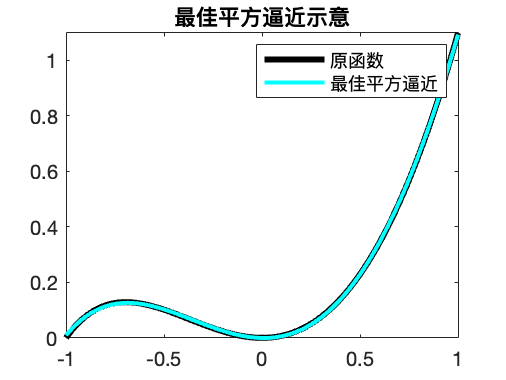


% Plot the approximated function
figure
plot(x_input,y_real,'-','LineWidth',3,'Color','k');hold on;
plot(x_input,y_sqr,'-','LineWidth',2,'Color','c');
legend('原函数','最佳平方逼近');
title("最佳平方逼近示意");

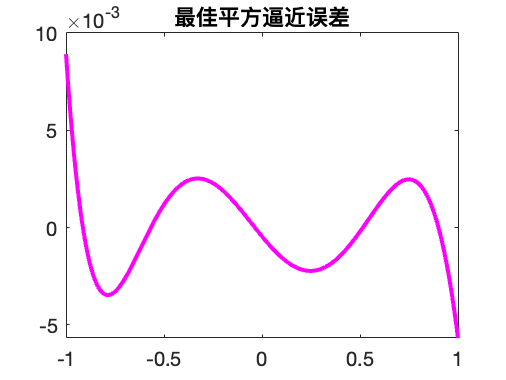


% Plot the error
figure
plot(x_input,y_sqr-y_real,'-','LineWidth',2,'Color','m');
title("最佳平方逼近误差");

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Best uniform approximation
% Compare the error (two kinds of norms of the residual) 
% with the former method.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Get the coefficient
a_tche=tche_approx(func,n);

% Get approximated function
func_tche=@(x)0;                                                     
for i=1:n+1
    func_tche=@(x)func_tche(x)+a_tche(i).*subs(Tn(i),y,x);
end

% Start approximating
y_tche=double(func_tche(x_input));

% Error
err_tche_2=norm(y_tche-y_real,2);               % Residual in 2-norm
err_tche_inf=norm(y_tche-y_real,inf);           % Residual in infinite-norm
fprintf("2范数误差：%f",err_tche_2);

2范数误差：0.129776

fprintf("无穷范数误差：%f",err_tche_inf);

无穷范数误差：0.047403

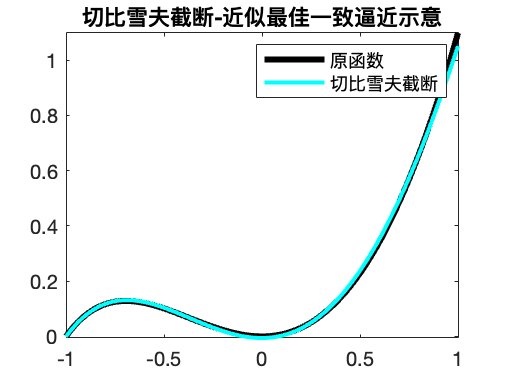


% Plot the approximated function
figure
plot(x_input,y_real,'-','LineWidth',3,'Color','k');hold on;
plot(x_input,y_tche,'-','LineWidth',2,'Color','c');
legend('原函数','切比雪夫截断');
title("切比雪夫截断-近似最佳一致逼近示意");

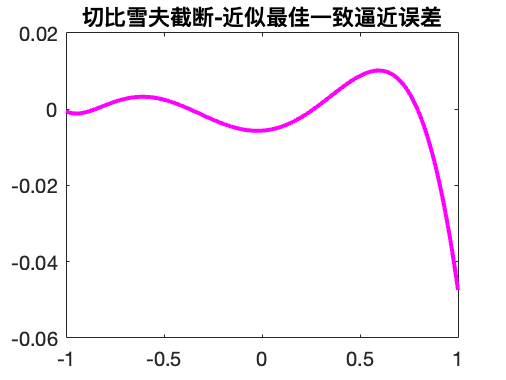


% Plot the error
figure
plot(x_input,y_tche-y_real,'-','LineWidth',2,'Color','m');
title("切比雪夫截断-近似最佳一致逼近误差");

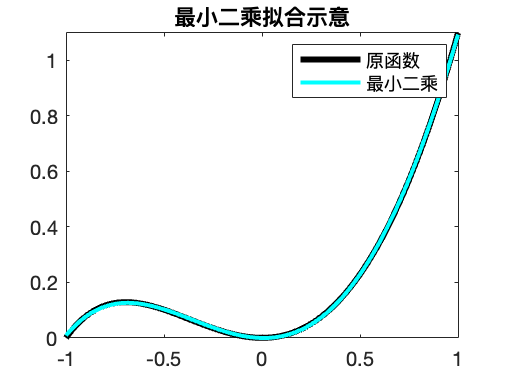

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Least square method
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[coeff]=least_square(x_input',y_real',n);
syms x
S=@(x)0;
for i=1:n+1
    S=@(x)(S(x)+coeff(i).*x.^(n-i+1));
end
y_least=S(x_input);

% Plot the approximated function
figure
plot(x_input,y_real,'-','LineWidth',3,'Color','k');hold on;
plot(x_input,y_least,'-','LineWidth',2,'Color','c');
legend('原函数','最小二乘');
title("最小二乘拟合示意");

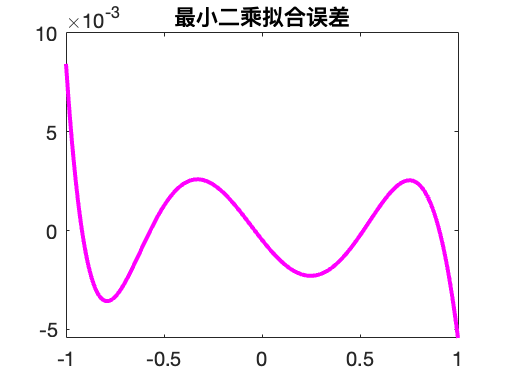


% Plot the error
figure
plot(x_input,y_least-y_real,'-','LineWidth',2,'Color','m');
title("最小二乘拟合误差");

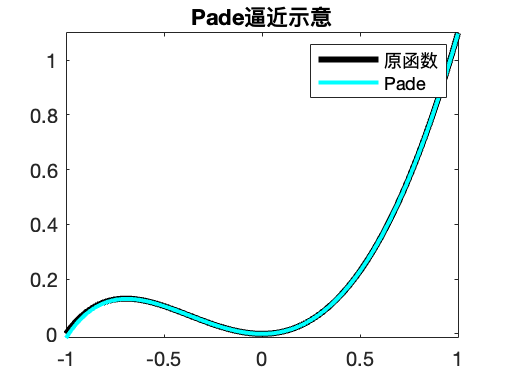

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pade approximation
% You can change m and n and see the change of the curve.
% Compare the precision among these approximations. 
% What is the advantage of Pade approximation ?
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
m=4;
n=6;

% Get cofficient
[p,q]=pade_approx(func,m,n);

% Get approximated function
Q=@(x)0;
P=@(x)0;
for i=1:m
    Q=@(x)(Q(x)+q(i).*x.^(i-1));
end
for i=1:n
    P=@(x)(P(x)+p(i).*x.^(i-1));
end
Rmn=@(x)P(x)./Q(x);

% Calculate y
y_pade=Rmn(x_input);


% Plot the approximated function
figure
plot(x_input,y_real,'-','LineWidth',3,'Color','k');hold on;
plot(x_input,y_pade,'-','LineWidth',2,'Color','c');
legend('原函数','Pade');
title("Pade逼近示意");

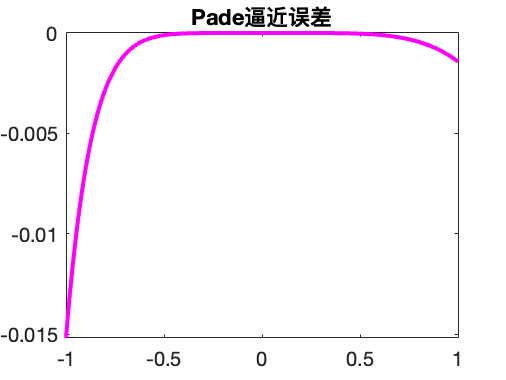


% Plot the error
figure
plot(x_input,y_pade-y_real,'-','LineWidth',2,'Color','m');
title("Pade逼近误差");